%KL冰芯非海盐硫酸根序列定年
clc;clear
%% Find All Peaks
TZdata=xlsread('youdata.xlsx');
nssSOdata = TZdata(1:530,8);
deepdata = TZdata(1:530,11);

%a = table2array(KLdata);
a = nssSOdata;

data = a;
for i = 1:2
    meanValue = mean(data); % 计算data的平均值
    stdValue = std(data); % 计算data的标准偏差
    threshold = meanValue + 2*stdValue; % 计算2倍标准偏差的阈值
    data(data>threshold) = []; % 去除大于阈值的数据
end

twoStdLine = meanValue + 2*stdValue; % 2倍标准偏差水平线


## 作图

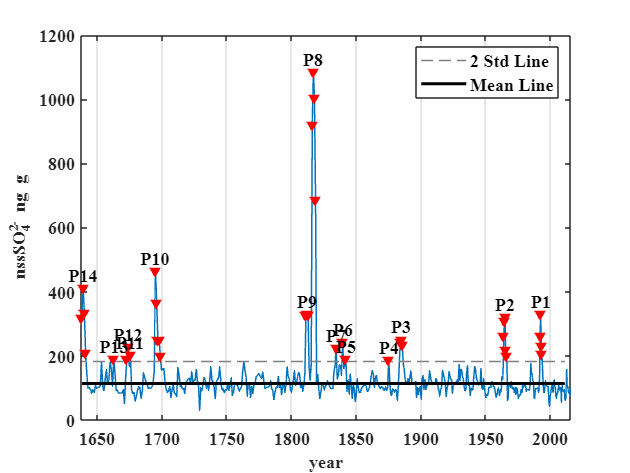

clf;
figure;
plot(deepdata,a,'Color',[0.00,0.45,0.74],'LineWidth',1); % 画出原始时间序列
hold on;
h1 = plot([1, 2011], [twoStdLine, twoStdLine],'Color',[0.5 0.5 0.5],'LineStyle','--','LineWidth',1); % 在图上画出2倍标准偏差水平线

h2 = plot([1, 2011], [meanValue,meanValue],'k','LineStyle','-','LineWidth',2);

% 标注大于2倍标准偏差的点
above_two_std = a(a > twoStdLine);
scatter(deepdata(a > twoStdLine), above_two_std,'Marker','v','MarkerEdgeColor',[1 0 0], 'MarkerFaceColor', [1 0 0]);

% 找出峰值
% 找到大于2倍标准偏差水平线的峰值并标注
% text(locs, pks, num2str((1:length(pks))'))
[pks, locs] = findpeaks(a, 'MinPeakHeight', twoStdLine); % 找到大于2倍标准偏差水平线的峰值

% 在每个峰值处添加标注
for i = 1:length(locs)
    text(deepdata(locs(i)), a(locs(i)) + 5, ['P', num2str(i)], 'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'center');
end

% 设置 x 轴和 y 轴标签
xlabel('year')
ylabel('nssSO_{4}^{2-} ng g')

% 添加图例
legend([h1, h2], '2 Std Line', 'Mean Line')

% 设置 x 轴的范围
xlim([min(deepdata) max(deepdata)])

% 开启 x 轴的网格线
set(gca, 'XGrid', 'on');

% 设置字体属性
set(findall(gcf, '-property', 'FontName'), 'FontName', 'Times New Roman', 'FontSize', 12, 'FontWeight', 'bold');